# Comprobación para topología usada en NaiveDijkstra

N=10;%Number of disjoint links to compute
topology='SpineLeaf';
k=8;
source='L1';
dest='L3';

G=graphTopology(false,false,topology,k,10);

paths=edgeDisjointPair(G,source,dest,N,false);

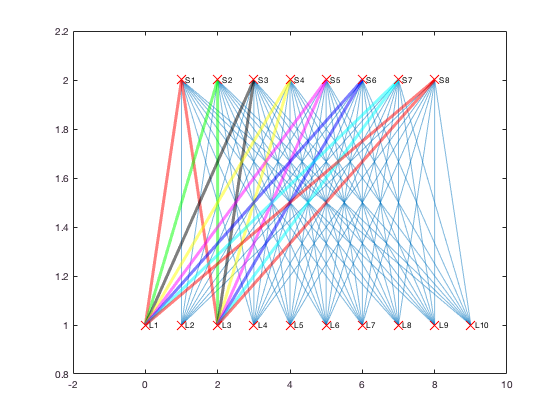

count = 1


%See the plot

p=plotGraphtopology(G);
list_color={'c','r','g','k','y','m','b'};
count=1;
for j=1:N
    count=count+1;
    if(count>7)
        count=1;
    end
    highlight(p,paths{j},'EdgeColor',list_color{count},'LineWidth',3);
end

# Comparación DisjointPair con NaiveDijkstra

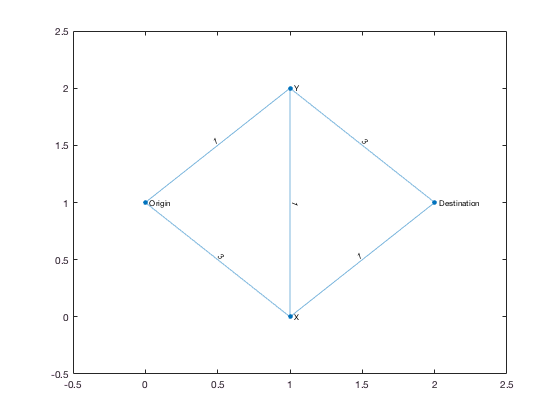

nnodes=4;
N=3;
% Nodes Table
endnodes = cell(nnodes, 1);
Xpoint(nnodes,1)=1;
Ypoint(nnodes,1)=1;
endnodes{1}='Origin';
Xpoint(1,1)=0;
Ypoint(1,1)=1;
endnodes{2}='Y';
Xpoint(2,1)=1;
Ypoint(2,1)=2;
endnodes{3}='X';
Xpoint(3,1)=1;
Ypoint(3,1)=0;
endnodes{4}='Destination';
Xpoint(4,1)=2;
Ypoint(4,1)=1;
nodestable = table(endnodes,Xpoint,Ypoint,'VariableNames',{'Name';'Xpoint';'Ypoint'});

edges=[1 2; 1 3; 2 3; 2 4; 3 4];
costs=[ 1; 3; 1; 3; 1];

NetCostMatrix=[0 1 3 0; 1 0 1 3; 3 1 0 1; 0 3 1 0];

edgetable = table(edges,costs,'VariableNames',{'EndNodes';'Weight'});
G=graph(edgetable,nodestable);

p = plot(G,'XData',G.Nodes.Xpoint','YData',G.Nodes.Ypoint','NodeLabel',G.Nodes.Name,'EdgeLabel', G.Edges.Weight);

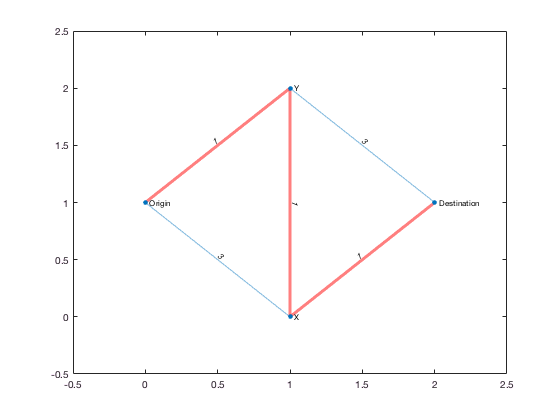

paths=edgeDisjointNaiveDijkstra(NetCostMatrix,1,4,N,true);

%See the plot

p = plot(G,'XData',G.Nodes.Xpoint','YData',G.Nodes.Ypoint','NodeLabel',G.Nodes.Name,'EdgeLabel', G.Edges.Weight);
list_color={'c','r','g','k','y','m','b'};
count=1;
for j=1:N
    count=count+1;
    if(count>7)
        count=1;
    end
    highlight(p,paths{j},'EdgeColor',list_color{count},'LineWidth',3);
end

## El NaiveDijkstra solo encuentra una ruta disjunta

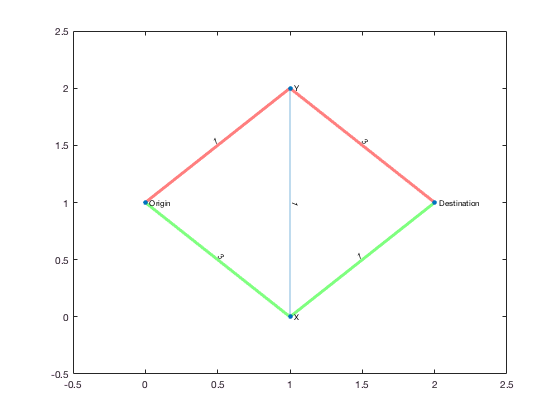

paths=edgeDisjointPair(NetCostMatrix,1,4,N,true);

%See the plot

p = plot(G,'XData',G.Nodes.Xpoint','YData',G.Nodes.Ypoint','NodeLabel',G.Nodes.Name,'EdgeLabel', G.Edges.Weight);
list_color={'c','r','g','k','y','m','b'};
count=1;
for j=1:N
    count=count+1;
    if(count>7)
        count=1;
    end
    highlight(p,paths{j},'EdgeColor',list_color{count},'LineWidth',3);
end

## El DisjointPair encuentra dos rutas disjuntas